# t_sliceTiming

Illustrates how to slice time correct an fMRI data set using sample data set [erniePRF](erniePRF)

Dependencies: Remote Data Toolbox

This tutorial is part of a sequence. Run 

- t_initAnatomyFromFreesurfer 

- t_meshesFromFreesurfer 

- *optional t_initVistaSession 

- t_alignInplaneToVolume 

- *optional 

- t_installSegmentation 

*optional prior to running this tutorial. 

**Summary**

- Specify alignment matrix linking inplane anatomy to volume anatomy

- Save mrSESSION with alignment matrix

Tested 07/21/2016 - MATLAB r2015a, Mac OS 10.11.6 

`See also: t_initAnatomyFromFreesurfer t_initVistaSession t_alignInplaneToVolume`

Winawer lab (NYU)

## Start

Clean start in case we have a vista session open

mrvCleanWorkspace();

% Remember where we are
curdir = pwd();

## Organize functional data

% Find ernie PRF session in scratch directory
erniePathTemp      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');

if ~exist(erniePathTemp, 'dir')
    help(mfilename)
    error('Please run  pre-requisite tutorials')
end

% Navigate and create a directory
cd(erniePathTemp)

## Compute slice timing correction

% Open a hidden view (a session without graphical user interface)
vw = initHiddenInplane();

    
% We will slice time correct the Original (uncorrected) data
vw = viewSet(vw, 'Current DataTYPE', 'Original');

nScans   = viewGet(vw, 'number of scans');
nSlices  = viewGet(vw, 'number of slices');

% These data were acquired by a Seimens scanner with interleaved slice
%   acquistition (2:2:end, 1:2:end-1)

sliceOrder = [2:2:nSlices 1:2:nSlices-1];

% Ensure that slice order is set in mrSESSION file. If it is not already
%   set, then set it now. It is possible but not requierd to set this at
%   session initialization.
for scan = 1:nScans    
    if isempty(sessionGet(mrSESSION, 'sliceorder', scan))
        mrSESSION = sessionSet(mrSESSION, 'sliceorder', sliceOrder, scan);
        % Save the mrSESSION so that the slice timeing order will be saved
        saveSession();
    end    
end

% Apply the slice timing correction
if any(strcmpi({dataTYPES.name}, 'Timed'))
    % Do not apply slice timing if it was already done
    warning('Slice time correction has already been done on this data set.')
else
    % Do it
    vw = AdjustSliceTiming(vw, 1:nScans, 'Timed', 1:nSlices);
end

## Visualize

% Define two point ROIs in visual cortex. The first point is in slice 2.
%   Because slice 2 was acquired first in each TR, its time series will be
%   adjusted forward. The second point is in slice 21. It was acquired near
%   the end of the TR so it will be adjusted backward.
coords1 = [153 107 2]';
coords2 = [127 83 21]';

% get the original and slice-time corrected tseries
scan        = 1;
getRawData  = false;

[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [52.000,40.000,12.000] pix.


[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [52.000,40.000,12.000] pix.


vw        = viewSet(vw, 'current dataTYPE', 'Original');
tsOrig1   = meanTSeries(vw,scan,coords1, getRawData);
tsOrig2   = meanTSeries(vw,scan,coords2, getRawData);

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


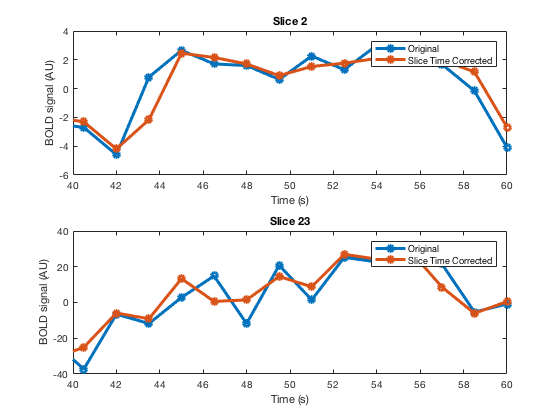

vw        = viewSet(vw, 'current dataTYPE', 'Timed');
tsTime1   = meanTSeries(vw,scan,coords1, getRawData);
tsTime2   = meanTSeries(vw,scan,coords2, getRawData);

t = (1:viewGet(vw, 'num frames')) * viewGet(vw, 'tr');

% plot it
newGraphWin();
subplot(2,1,1)
plot(t, tsOrig1, 'o-', t, tsTime1, 'o-', 'LineWidth', 3)
legend('Original', 'Slice Time Corrected');
set(gca, 'XLim', [40 60])
xlabel('Time (s)'), ylabel('BOLD signal (AU)')
title ('Slice 2')

subplot(2,1,2)
plot(t, tsOrig2,'o-', t, tsTime2, 'o-', 'LineWidth', 3)
legend('Original', 'Slice Time Corrected');

set(gca, 'XLim', [40 60])
xlabel('Time (s)'), ylabel('BOLD signal (AU)')
title ('Slice 23')

% Note that for slice 2, the corrected tseries is delayed whereas for slice
% 21, the corrected tseries is advanced. In both cases, the tseries is also
% modestly blurred due to the resampling.

## Clean up

close(viewGet(vw, 'figure number')); 
mrvCleanWorkspace
cd(curdir)